% Step1: 
% If you have the mean and variance you have the Gaussian distribution
% Generate data from 2D Gaussian distribution

% component1
mu1 = [1 2]; %mean
sigma1 = [ 3 .2;  % covariance matrix 
          .2  2];
m1 = 200;  % number of data points        

% component2
mu2 = [-1 -2];  % mean
sigma2 = [2 0;  % covariance matrix
          0 1];
m2 = 100;   % number of data points

% generate sample points with the means and covarinace matrix above

% component1
R1 = chol(sigma1);  % Cholesky factorization -> covariance decomposition
X1 = randn(m1, 2) * R1; % generate bivariate normal numbers (size of data points)
X1 = X1 + repmat(mu1, size(X1, 1), 1);  % distribution with mean specified

% component2
R2 = chol(sigma2);
X2 = randn(m2, 2) * R2;
X2 = X2 + repmat(mu2, size(X2, 1), 1);

% combine component1 and component2
X = [X1; X2];

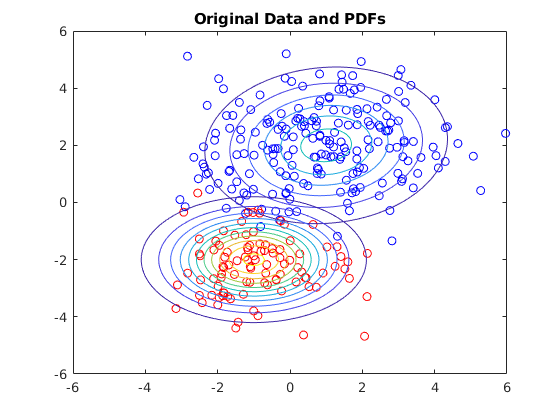

% Step2:
% Plot the data points and their pdfs (probability density function)
% Display the scatter plot of the two distribution
figure(1);

hold off;

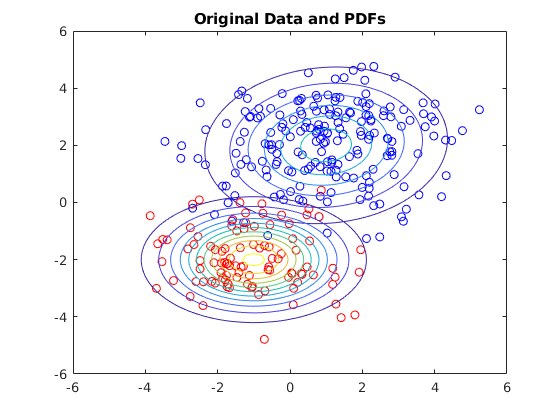

plot(X1(:, 1), X1(:, 2), 'bo');
hold on;
plot(X2(:, 1), X2(:, 2), 'ro');
set(gcf,'color','white') % the figure is in white background

% create a matrix girdX (x,y coordinates) as the input values over the grid (range from -6 to 6)
addpath('GMM_Examples/');
gridSize = 100;
u = linspace(-6, 6, gridSize);
[A B] = meshgrid(u, u);
gridX = [A(:), B(:)];   % shape to 1D
% calculate the Gaussian response (probability density function) for every value in the grid
z1 = gaussianND(gridX, mu1, sigma1);
z2 = gaussianND(gridX, mu2, sigma2);

% reshape back to 2D
Z1 = reshape(z1, gridSize, gridSize);
Z2 = reshape(z2, gridSize, gridSize);

% Plot the contour lines to show the Gaussian response (PDFs)
[C, h] = contour(u, u, Z1);
[C, h] = contour(u, u, Z2);

axis([-6 6 -6 6])
title('Original Data and PDFs');

% Step3
% Choose initial values for the parameters (K-means clustering)
m = size(X, 1); % m is the number of data points
k = 2;  % the number of clusters
n = 2;  % the vector lengths

 % randomly select k data points as the initial cluster centers
indeces = randperm(m); 
mu = X(indeces(1:k), :);

sigma = [];
for (j = 1 : k)
    sigma{j} = cov(X);  % use the overall covariance of the dataset as the initial vairance for each cluster
end

% Initialize equal probabilities to each cluster.
phi = ones(1, k) * (1 / k);

% Step4
% run expectation maximization (EM step)
% EM: find blob parameters theta that maximize the likelihood function
W = zeros(m, k);    % probability matrix -> the probability of each data point belong to each cluster

% Loop until convergence (enough iterations that guaratee convergence -> at most 1000 iterations)
for (iter = 1:1000)
    fprintf('  EM Iteration %d\n', iter);
    
    % E step(Expectation): given guess of blobs, compute ownership of each point
    % Evaluate the Gaussian for all data points for cluster 'j'
    for (j = 1 : k)
        pdf(:, j) = gaussianND(X, mu(j, :), sigma{j});
    end
    
    % Multiply each pdf value by the prior probability for cluster
    pdf_w = bsxfun(@times, pdf, phi);
    
    % Divide the weighted probabilities by the sum of weighted probabilities for each cluster.
    %   sum(pdf_w, 2) -- sum over the clusters. (new probability)
    W = bsxfun(@rdivide, pdf_w, sum(pdf_w, 2));

    % M step (Maximization): given ownership probabilities, update blobs to
    % maximize likelihood function
    % Calculate the probability for each distribution
    
    % store the previous mean
    prevMu = mu;    

    % for each cluster j
    for (j = 1 : k)
        phi(j) = mean(W(:, j), 1);  % calculate the probability for cluster j
        mu(j, :) = weightedAverage(W(:, j), X); % calculate the new mean (average of ll data points)

        % calculate the covariance matrix for cluster j (weighted average of the covariance for each training example)
        sigma_k = zeros(n, n);
        Xm = bsxfun(@minus, X, mu(j, :));   % subtract the cluster mean from all the data points
        
        % calculate the contribution of each training example to the covariance matrix
        for (i = 1 : m)
            sigma_k = sigma_k + (W(i, j) .* (Xm(i, :)' * Xm(i, :)));
        end
        
        % the new covariance matrix (sigma_k divide by the sum of weights) 
        sigma{j} = sigma_k ./ sum(W(:, j));
    end
    
    % check for convergence (if cluster centers remains the same)
    if (mu == prevMu)
        break
    end
end

  EM Iteration 1
  EM Iteration 2
  EM Iteration 3
  EM Iteration 4
  EM Iteration 5
  EM Iteration 6
  EM Iteration 7
  EM Iteration 8
  EM Iteration 9
  EM Iteration 10
  EM Iteration 11
  EM Iteration 12
  EM Iteration 13
  EM Iteration 14
  EM Iteration 15
  EM Iteration 16
  EM Iteration 17
  EM Iteration 18
  EM Iteration 19
  EM Iteration 20
  EM Iteration 21
  EM Iteration 22
  EM Iteration 23
  EM Iteration 24
  EM Iteration 25
  EM Iteration 26
  EM Iteration 27
  EM Iteration 28
  EM Iteration 29
  EM Iteration 30
  EM Iteration 31
  EM Iteration 32
  EM Iteration 33
  EM Iteration 34
  EM Iteration 35
  EM Iteration 36
  EM Iteration 37
  EM Iteration 38
  EM Iteration 39
  EM Iteration 40
  EM Iteration 41
  EM Iteration 42
  EM Iteration 43
  EM Iteration 44
  EM Iteration 45
  EM Iteration 46
  EM Iteration 47
  EM Iteration 48
  EM Iteration 49
  EM Iteration 50
  EM Iteration 51
  EM Iteration 52
  EM Iteration 53
  EM Iteration 54
  EM Iteration 55
  EM Iteration 56
 

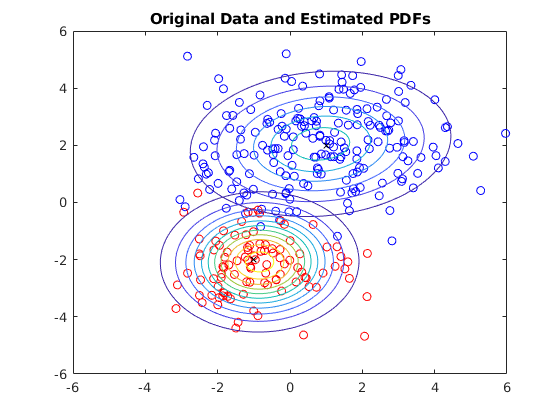

% Step5
% Plot the data points and their estimated PDFs (probability density functions)

% scatter plot of the two distributions
figure(2);
hold off;

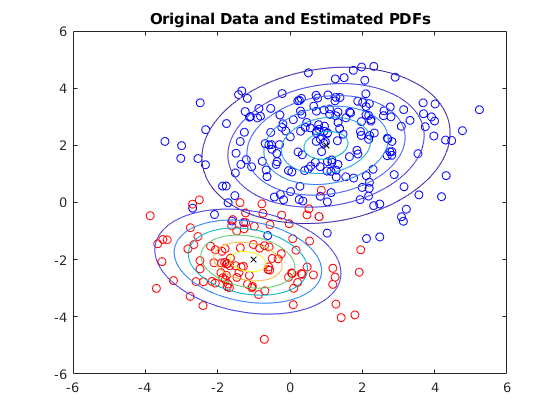

plot(X1(:, 1), X1(:, 2), 'bo');
hold on;
plot(X2(:, 1), X2(:, 2), 'ro');

set(gcf,'color','white'); % white background

plot(mu1(1), mu1(2), 'kx');
plot(mu2(1), mu2(2), 'kx');

% create a matrix girdX (x,y coordinates) as the input values over the grid (range from -6 to 6)
gridSize = 100;
u = linspace(-6, 6, gridSize);
[A B] = meshgrid(u, u);
gridX = [A(:), B(:)];    % shape of 1D

% calculate the Gaussian response (probability density function) for every value in the grid
z1 = gaussianND(gridX, mu(1, :), sigma{1});
z2 = gaussianND(gridX, mu(2, :), sigma{2});

% reshape back to 2D
Z1 = reshape(z1, gridSize, gridSize);
Z2 = reshape(z2, gridSize, gridSize);

% Plot the contour lines to show the Gaussian response (PDFs)
[C, h] = contour(u, u, Z1);
[C, h] = contour(u, u, Z2);
axis([-6 6 -6 6])

title('Original Data and Estimated PDFs');